cell2mat的升级版

本函数是cell2mat的升级版，使用前请先参阅cell2mat函数文档，了解其功能和局限性。

cell2mat是一个功能十分强大的MATLAB函数，可以将元胞数组内的数组提取出来，拼成一个大数组，而且这些数组的尺寸不必完全相同，例如可以支持以下拼接：

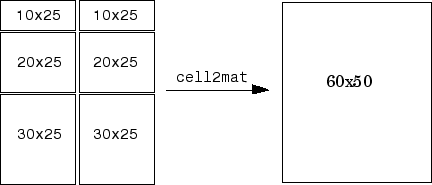

但它也存在局限性。首先，只支持数值、逻辑、结构体、字符的拼接，其它常见数据类型（字符串、元胞、类对象）都无法使用。其次。对于以下结构，虽然尺寸恰好合适，但也无法拼接：

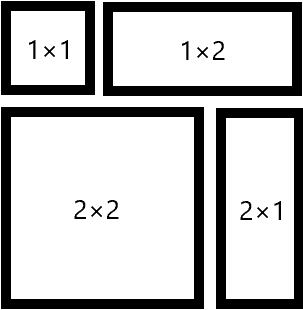

这是因为cell2mat默认先拼第1维，自然会遇到尺寸不匹配的问题。但我们可以看到，只要先拼第2维，就可以得到1×3和2×3两个矩阵，然后第1维就可以拼接了。本函数不仅支持各种数据类型，还会自动尝试从不同的维度进行拼接，因此支持更多复杂的结构。

输入参数：Cells cell，要拼接的元胞数组，各元胞内含有数据类型一致的数组，且各维尺寸上恰好可以拼接成一个大数组，维度不限。

返回值：拼接好的大数组

function Cells = SuperCell2Mat(Cells)
arguments
	Cells cell
end
Size=size(Cells);
NDims=ndims(Cells);
while true
	Cells=reshape(Cells,[],Size(end));
	Height=height(Cells);
	New=cell(Height,1);
	try
		for a=1:Height
			New{a}=cat(NDims,Cells{a,:});
		end
	catch
		Permute=1:NDims;
		NoProgress=true;
		for a=NDims-1:-1:1
			Permute([a end])=Permute([end a]);
			Size([a end])=Size([end a]);
			Cells=reshape(permute(Cells,Permute),[],Size(end));
			Height=height(Cells);
			New=cell(Height,1);
			try
				for b=1:Height
					New{b}=cat(a,Cells{b,:});
				end
				Size(end)=1;
				NoProgress=false;
			catch
			end
			Cells=permute(reshape(New,Size),Permute);
			Permute([a end])=Permute([end a]);
			Size([a end])=Size([end a]);
		end
		if NoProgress
			error("拼接失败，没有找到可以拼接的维度");
		end
		continue;
	end
	Size(end)=[];
	NDims=NDims-1;
	if NDims<2
		break;
	end
	Cells=reshape(New,Size);
end
Cells=vertcat(New{:});